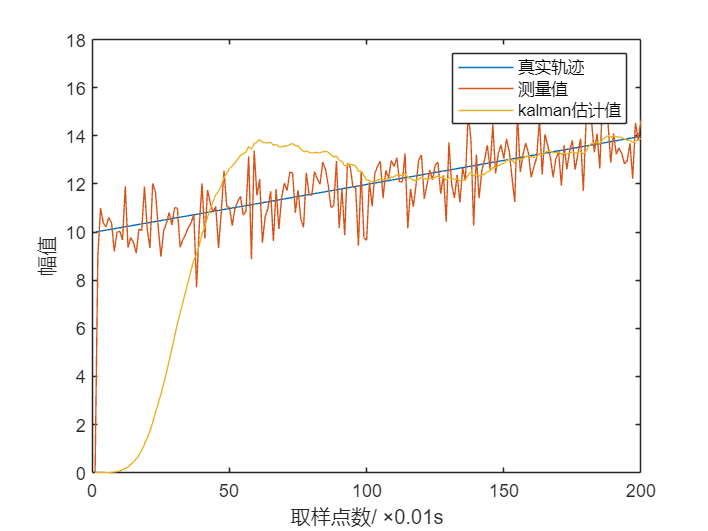

clc;
clear;

T = 0.01;   %采样间隔
sigma_1 = 0.1;
sigma_a = 1;
N = 200;

A = [1 T; 0 1];
C = [1 0];
Q = [0 0; 0 sigma_1];
R = sigma_a;
v = sqrt(sigma_a)*randn(1,N);
save('v01','v')
load('v01');

s = zeros(2,N);
s_estimate = zeros(2,N);
x = zeros(1,N);

xi = zeros(2);

%给定初始值
s(:,1) = [10 2]'; 
s_estimate(:,1) = [0 0];

%% Kalman 算法
for n=2:N
 
    s(:,n) = A*s(:,n-1);   %状态方程
    x(:,n) = C*s(:,n)+v(n);       %测量方程
         %kalman滤波算法
    P = A*xi*A'+Q;
    G = P*C'*(C*P*C'+R)^(-1);
    s_estimate(:,n) = A*s_estimate(:,n-1)+G*(x(:,n)-C*A*s_estimate(:,n-1));
    xi = P-G*C*P;
end

t = 1:200;
figure;
plot(t,s(1,:),t,x,t,s_estimate(1,:));
legend('真实轨迹','测量值','kalman估计值');
xlabel('取样点数/ ×0.01s');
ylabel('幅值');

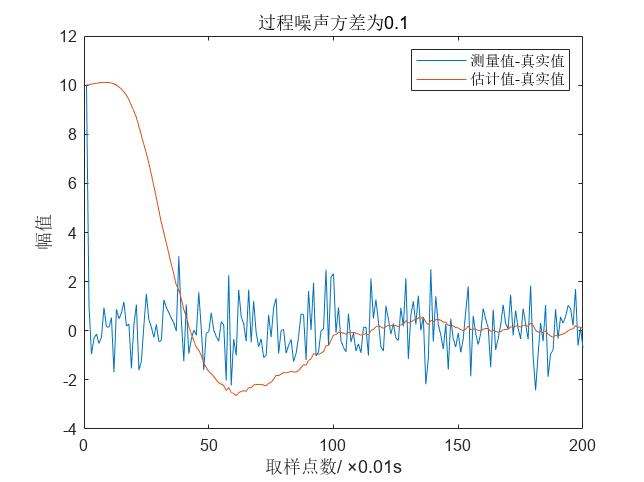


error1 = s(1,:)-x;
error2 = s(1,:)-s_estimate(1,:);
figure;
plot(t,error1,t,error2);
xlabel('取样点数/ ×0.01s');
ylabel('幅值');
legend('测量值-真实值','估计值-真实值');
title(['过程噪声方差为',num2str(sigma_1)]);